# XTD_C6: Decoding Peaks

% fileDirs = [{'D:\PFC\GE11_Session132'},...
%     {'D:\PFC\GE13_Session083'},...
%     {'D:\PFC\GE14_Session123'},...
%     {'D:\PFC\GE17_Session095'},...
%     {'D:\PFC\GE24_Session096'}];
fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);
nanWmap = rbDivMap;
nanWmap(1,:) = [1,1,1];

## Compile Data Across Rats

prevTrlLat = cell(1,4);
trialLightLat = cell(1,4);
pokeInLat = cell(1,4);
rwdSigLat = cell(1,4);
pokeOutLat = cell(1,4);
rwdLat = cell(1,4);
nxtTrlLat = cell(1,4);
for ani = 1:length(fileDirs)
    aniDta = load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'decPeaksNdx_Real', 'decPeaksNdx_ChanceFull', 'decPeaksNdx_ChancePos',...
        'decPeaksVal_Real', 'decPeaksVal_ChanceFull', 'decPeaksVal_ChancePos',...
        'decPeaksWid_Real', 'decPeaksWid_ChanceFull', 'decPeaksWid_ChancePos');   
    %%%
    fns = fieldnames(aniDta);
    if ani == 1
        for fn = 1:length(fns)
            eval(sprintf('%s = aniDta.%s;', fns{fn}, fns{fn}));
        end
    else
        for d = 1:numel(decPeaksNdx_Real)
            for fn = 1:length(fns)
                eval(sprintf('%s{d} = cat(3,%s{d}, aniDta.%s{d});', fns{fn}, fns{fn}, fns{fn}));
            end
        end
    end
    load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'trialInfo', 'mlb');
    cur_TrialInfo = cell2mat(trialInfo(cellfun(@(a)~isempty(a),trialInfo))');
    for pos = 1:mlb.seqLength
        curPosLog = [cur_TrialInfo.Position]==pos;
        if strcmp(mlb.alignments{1}, 'PokeIn')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeInIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
        elseif strcmp(mlb.alignmnents{1}, 'PokeOut')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]*-1];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeOutIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
        end
    end
end


## Plot Stuff

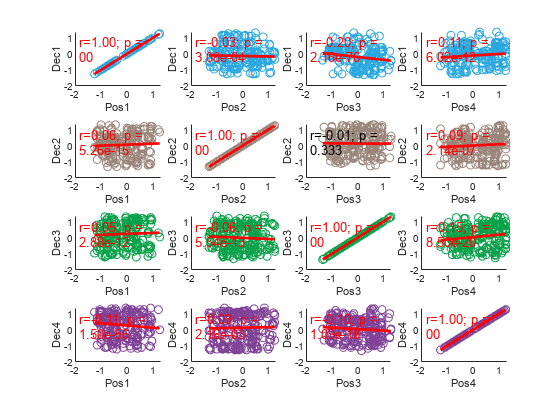

figure;
spsNDX = reshape(1:(mlb.seqLength^2), [mlb.seqLength,mlb.seqLength]);
sps = nan(size(spsNDX));
for trlPos = 1:mlb.seqLength
    curTrlDecPeaks = squeeze(decPeaksNdx_Real{trlPos,trlPos,trlPos}(trlPos,:,:));
    for decPos = 1:mlb.seqLength
        curDecDecPeaks = squeeze(decPeaksNdx_Real{trlPos,trlPos,trlPos}(decPos,:,:));
        sps(trlPos,decPos) = subplot(mlb.seqLength, mlb.seqLength, spsNDX(trlPos,decPos));
        mlb.CorrScatPlot(curTrlDecPeaks(:),curDecDecPeaks(:), sprintf('Pos%i',trlPos), sprintf('Dec%i',decPos), 'markerColor', mlb.PositionColors(decPos,:));
%         scatter(curTrlDecPeaks(:)',curDecDecPeaks(:)', 10, mlb.PositionColors(decPos,:), 'filled'); hold on;
    end
end
linkaxes(sps, 'xy');

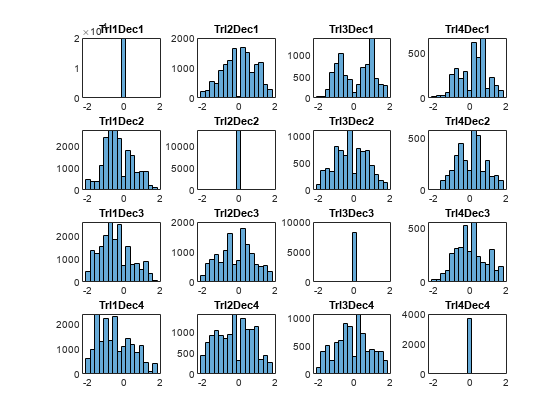


figure;
for trlPos = 1:mlb.seqLength
    curTrlDecPeaks = squeeze(decPeaksNdx_Real{trlPos,trlPos,trlPos}(trlPos,:,:));
    for decPos = 1:mlb.seqLength
        curDecDecPeaks = squeeze(decPeaksNdx_Real{trlPos,trlPos,trlPos}(decPos,:,:));
        curPeakDiffs = curTrlDecPeaks-curDecDecPeaks;
        sps(trlPos,decPos) = subplot(mlb.seqLength, mlb.seqLength, spsNDX(trlPos,decPos));
        histogram(curPeakDiffs, (-2:0.25:2)-0.125);
        title(sprintf('Trl%iDec%i', trlPos, decPos));
    end
end
linkaxes(sps,'x');

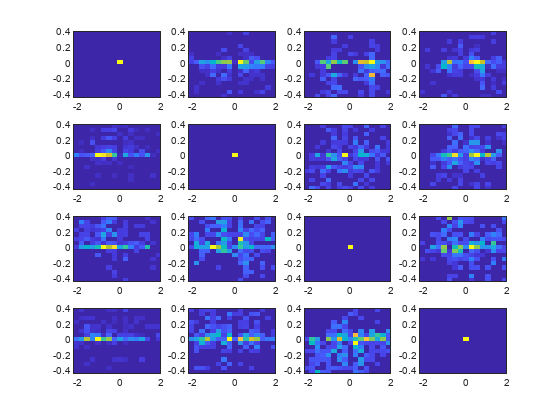

figure;
for trlPos = 1:mlb.seqLength
    curTrlDecPeaks = squeeze(decPeaksNdx_Real{trlPos,trlPos,trlPos}(trlPos,:,:));
    curTrlDecVals = squeeze(decPeaksVal_Real{trlPos,trlPos,trlPos}(trlPos,:,:));
    for decPos = 1:mlb.seqLength
        curDecDecPeaks = squeeze(decPeaksNdx_Real{trlPos,trlPos,trlPos}(decPos,:,:));
        curPeakDiffs = curTrlDecPeaks - curDecDecPeaks;
        curDecDecVals = squeeze(decPeaksVal_Real{trlPos,trlPos,trlPos}(decPos,:,:));
        curValDiffs = curTrlDecVals - curDecDecVals;
        [tempCounts,xEdge,yEdge] = histcounts2(curPeakDiffs,curValDiffs,(-2:0.25:2)-0.125,(-0.4:0.05:0.4)-0.025);
        sps(trlPos,decPos) = subplot(mlb.seqLength, mlb.seqLength, spsNDX(trlPos,decPos));
        imagesc(xEdge,yEdge,tempCounts');
        set(sps(trlPos,decPos),'ydir','normal')
    end
end

## Stats